# **RS-HL-6: Ground Station and Satellite Contact Simulation**

**Hongseok Kim**

**Oden Institute**

**6/24/2024**

## Scope

  The interesting part of the satellite contact chart simulation is that the number of connection oscillates fastly between two integers. We need to find the cause of the oscillation. In order to do that, we should visualize the contact sequence between single Ground Station to multiple satellites and single satellite to multiple ground stations. 

clc; clear;
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_1_Constellation_Scinario_Formulation/')


## I. Input information

### I.1 Time Parameter

% Initial Epoch Definition

Year = 2024;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = hours(24);
steptime = 15; % seconds

startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);

time_parameters.startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
time_parameters.duration = duration;
time_parameters.steptime = steptime;

scenario = scenario_initalization(time_parameters);



### I.2 Satellite Constellation - Walker Configuration (24 SATs in Single Orbit)

% Intial Orbit Settings

Altitude = 500; % (km)
Eccentricity = 1e-5;
Inclinaton = 97.4022; % (deg)
RAAN = 90;  % (deg)
AOP = 0; % (deg)

% Number of satellites
number_of_SATs = 24;

% Satellite Characteristics - This will entail -1, -2, ... for
% constallation
satellite_name = "RS-1";

% Orbit Propagator
Orbit_Propagator = 'SGP4';


orbit_information.SMA = Altitude*1000 + 6378000;
orbit_information.ecc = Eccentricity;
orbit_information.inc = Inclinaton;
orbit_information.RAAN = RAAN;
orbit_information.AOP = AOP;

% Generate First Stream of Satellites
satellites_orbit_1 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);


% Generate Second Steram of Satellites
RAAN = 105;
orbit_information.RAAN = RAAN;
satellite_name = "RS-2";
satellites_orbit_2 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);

% Merge Satellite Informations
satellites = [satellites_orbit_1, satellites_orbit_2];



### I.4 gs Station Location

gs_info = ["Austin", 30.2672, -97.7431, 15;
           "New York", 40.7128, -74.0060, 10;
           "Los Angeles", 34.0522, -118.4837, 71;
           "Chicago", 41.8781, -87.6298, 181;
           "Houston", 29.7604, -95.3698, 30;
           "Phoenix", 33.4484, -112.0740, 331;
           "Philadelphia", 39.9526, -75.1652, 12;
           "San Antonio", 29.4481, -98.4936, 198;
           "San Diego", 32.7157, -117.1611, 22;
           "Dallas", 32.7767, -96.7970, 137;
           "London", 51.5074, -0.1278, 35;
           "Tokyo", 35.6895, 139.6917, 6;
           "Paris", 48.8566, 2.3522, 35;
           "Moscow", 55.7558, 37.6176, 155;
           "Sydney", -33.8688, 151.2093, 19;
           "Toronto", 43.6511, -79.3830, 76;
           "Berlin", 52.5200, 13.4050, 34;
           "Rome", 41.9028, 12.4964, 17;
           "Seoul", 37.5665, 126.9780, 23;
           "Mumbai", 19.0760, 72.8777, 14;
           "Beijing", 39.9042, 116.4074, 43;
           "Mexico City", 19.4326, -99.1332, 2240;
           "São Paulo", -23.5505, -46.6333, 780;
           "Bangkok", 13.7563, 100.5018, 2;
           "Istanbul", 41.0082, 28.9784, 39;
           "Cairo", 30.0444, 31.2357, 23;
           "Dubai", 25.2769, 55.2963, 4;
           "Singapore", 1.3521, 103.8198, 15;
           "Hong Kong", 22.3193, 114.1694, 39;
           "Sydney", -33.8688, 151.2093, 19];



gs = groundStation(scenario,"Name",gs_info(:,1), ...
                        "Latitude",str2double(gs_info(:,2)), ...
                        "Longitude", str2double(gs_info(:,3)), ...
                        "Altitude", str2double(gs_info(:,4)), ...
                        "MinElevationAngle", 15);


## II. GS -> SAT: Select 1 GS and 48 SATs in given timeframe

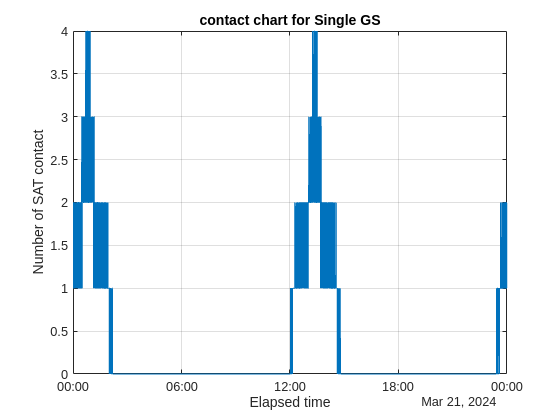

gs_no = 1;


[time_vector, ...
  gs_to_sat_access_table, ...
  gs_to_sat_access_matrix, ...
  gs_to_sat_access_info, ...
  contact_1_sat, ...
  contact_2_sat, ...
  contact_3_sat, ...
  contact_4_plus_sat] = gs_to_sat_access_info_generation(scenario,satellites,gs(gs_no));

figure;
plot(time_vector,gs_to_sat_access_matrix(1,:))
title('contact chart for Single GS')
xlabel('Elapsed time')
ylabel('Number of SAT contact')
grid on

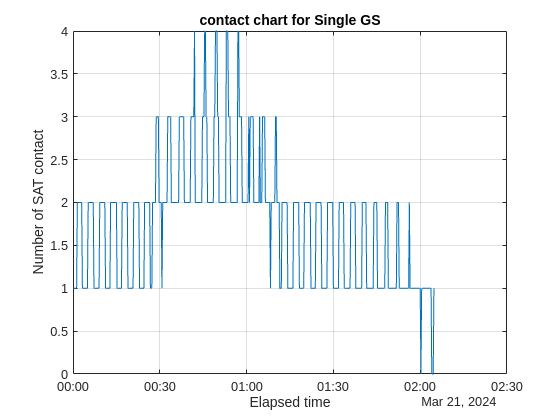


figure;
plot(time_vector(1:500),gs_to_sat_access_matrix(1,1:500))
title('contact chart for Single GS')
xlabel('Elapsed time')
ylabel('Number of SAT contact')
grid on


sorted_table1 = sortrows(gs_to_sat_access_table, 4, 'ascend')

sorted_table1 = 111×8 table
     Source      Target      IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    _________    ______________    ____________________    ____________________    ________    __________    ________

    "Austin"    "RS-1-3"           1           21-Mar-2024 00:00:00    21-Mar-2024 00:03:00      180           1            1    
    "Austin"    "RS-1-2"           1           21-Mar-2024 00:01:30    21-Mar-2024 00:07:00      330           1            1    
    "Austin"    "RS-1-1"           1           21-Mar-2024 00:05:15    21-Mar-2024 00:11:00      345           1            1    
    "Austin"    "RS-1-24"          1           21

## III. SAT -> GS: Select 1 SAT and 30 GS in given timeframe

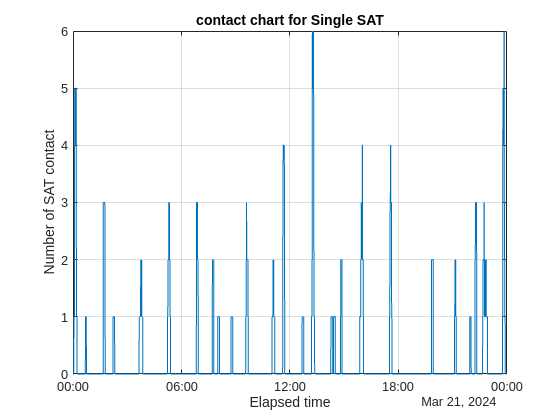

sat_no = 1;

[time_vector, ...
 sat_to_gs_access_table, ...
 sat_to_gs_access_matrix, ...
 sat_to_gs_access_info, ...
 contact_1_gs, ...
 contact_2_gs, ...
 contact_3_gs, ...
 contact_4_plus_gs] = sat_to_gs_access_info_generation(scenario,satellites(sat_no),gs);

figure;
plot(time_vector,sat_to_gs_access_matrix(1,:))
title('contact chart for Single SAT')
xlabel('Elapsed time')
ylabel('Number of SAT contact')
grid on

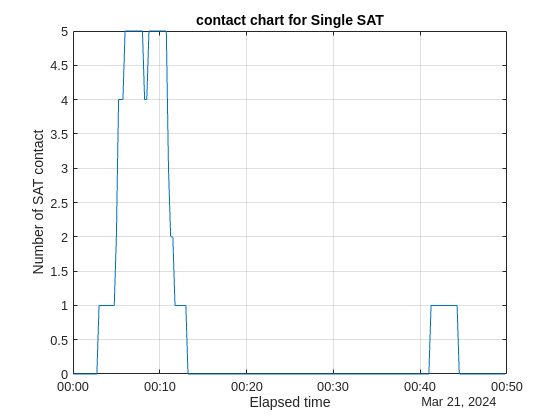


figure;
plot(time_vector(1:200),sat_to_gs_access_matrix(1,1:200))
title('contact chart for Single SAT')
xlabel('Elapsed time')
ylabel('Number of SAT contact')
grid on



sorted_table = sortrows(sat_to_gs_access_table, 4, 'ascend')

sorted_table = 75×8 table
     Source        Target        IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    _____________    ______________    ____________________    ____________________    ________    __________    ________

    "RS-1-1"    "Mexico City"          1           21-Mar-2024 00:03:00    21-Mar-2024 00:08:00      300           1            1    
    "RS-1-1"    "Houston"              1           21-Mar-2024 00:05:00    21-Mar-2024 00:10:45      345           1            1    
    "RS-1-1"    "Austin"               1           21-Mar-2024 00:05:15    21-Mar-2024 00:11:00      345           1            1    
    "RS-1-1"    "San Antonio"  